Задание 1

clear
tictactoe = readtable("tic_tac_toe.txt")

tictactoe = 957×10 table
      x       x_1      x_2      x_3       o       o_1      x_4      o_2      o_3       positive  
    _____    _____    _____    _____    _____    _____    _____    _____    _____    ____________

    {'x'}    {'x'}    {'x'}    {'x'}    {'o'}    {'o'}    {'o'}    {'x'}    {'o'}    {'positive'}
    {'x'}    {'x'}    {'x'}    {'x'}    {'o'}    {'o'}    {'o'}    {'o'}    {'x'}    {'positive'}
    {'x'}    {'x'}    {'x'}    {'x'}    {'o'}    {'o'}    {'o'}    {'b'}    {'b'}    {'positive'}
    {'x'}    {'x'}    {'x'}    {'x'}    {'o'}    {'o'}    {'b'}    {'o'}    {'b'}    {'positive'}
    {'x'}    {'x'}    {'x'}    {'x'}    {'o'} 

spam = readtable("spam.csv")

spam = 4601×59 table
    Var1    make    address    all     num3d    our     over    remove    internet    order    mail    receive    will    people    report    addresses    free    business    email    you     credit    your    font    num000    money    hp    hpl    george    num650    lab    labs    telnet    num857    data    num415    num85    technology    

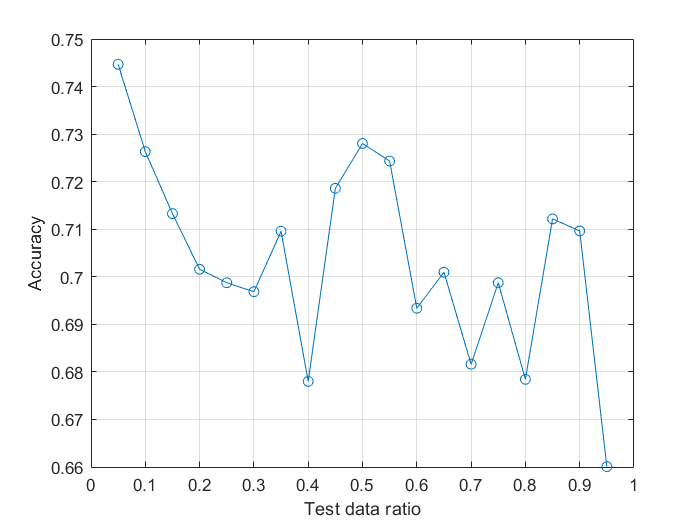

plotDependence(tictactoe, "mvmn");

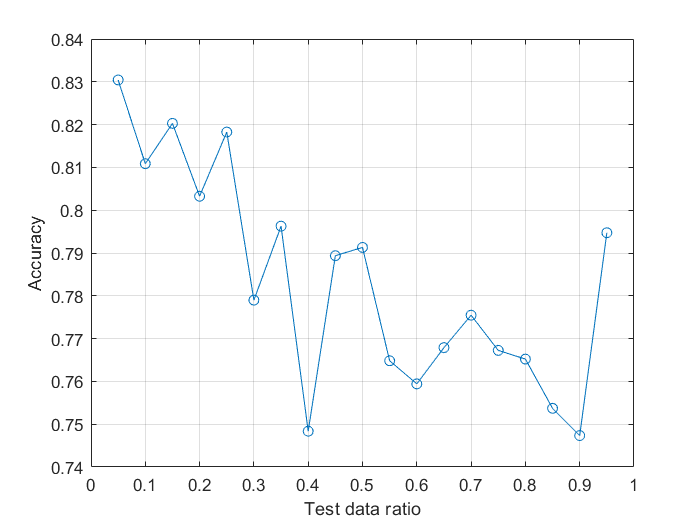

plotDependence(spam,"kernel");

Задание 2

clear
N = 100;
Nminus = 10;
Nplus = N - Nminus;

M1minus = 15;
M2minus = 18;
Dminus = 4;
M1plus = 18;
M2plus = 18;
Dplus = 2;

X1 = zeros(N,1);
X1(1:Nminus) = randn(Nminus,1).*sqrt(Dminus) + M1minus;
X1(Nminus+1:N) = randn(Nplus,1).*sqrt(Dplus) + M1plus;

X2 = zeros(N,1);
X2(1:Nminus) = randn(Nminus,1).*sqrt(Dminus) + M2minus;
X2(Nminus+1:N) = randn(Nplus,1).*sqrt(Dplus) + M2plus;

results = ones(N,1);
results(1:Nminus) = -1;

data = table(X1,X2,results,'VariableNames',{'X1','X2','Class'})

data = 100×3 table
      X1        X2      Class
    ______    ______    _____

    18.312    18.181     -1  
    13.723    15.035     -1  
    13.344    19.998     -1  
    17.785    21.753     -1  
    14.438    13.995     -1  
    13.785    19.351     -1  
    12.805    18.303     -1  
    16.775    17.989     -1  
    14.072    18.997     -1  
    14.828    19.084     -1  
    20.621    17.838      1  
    16.887    17.649      1  
    17.957    17.694      1  
    16.658    18.402      1  
    17.916    15.888      1  
    20.088    16.323      1  


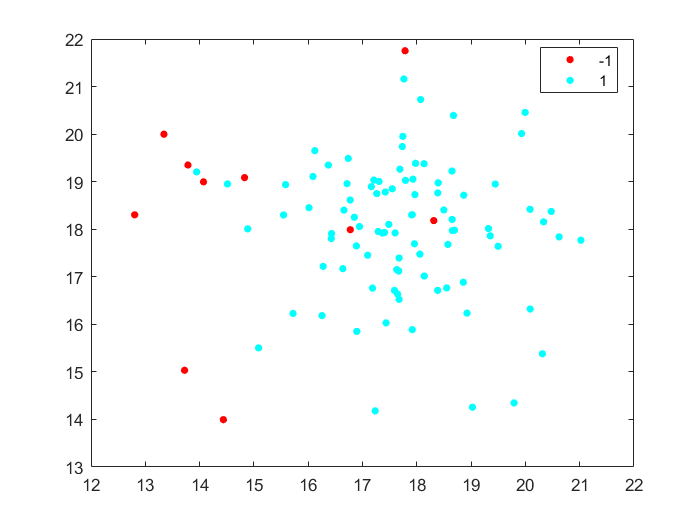

gscatter(data.X1,data.X2,data.Class)

cvpt = cvpartition(data.Class,"HoldOut",0.4);
dataTrain = data(training(cvpt),:);
dataTest = data(test(cvpt),:);
nbModel = fitcnb(dataTrain,"Class");
[prediction, scores] = predict(nbModel,dataTest);

accuracy = nnz(prediction == dataTest{:,end})/numel(prediction)

accuracy = 0.9500

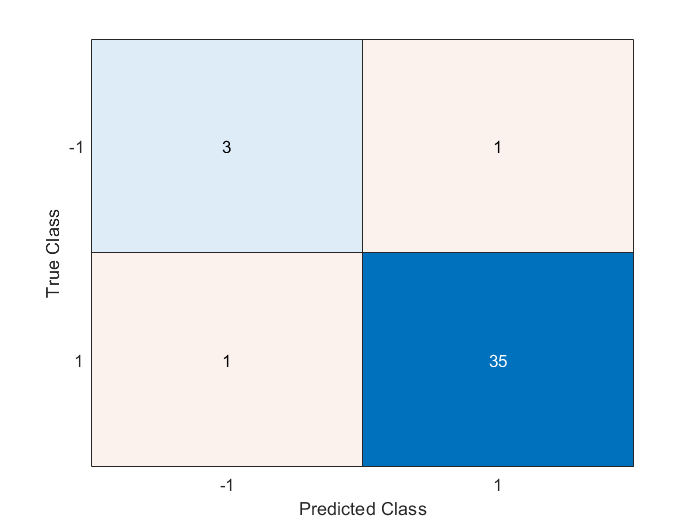

confusionchart(dataTest{:,end},prediction)


[X,Y,T,AUC] = perfcurve(dataTest.Class,scores(:,1),'-1');
AUC

AUC = 0.8125

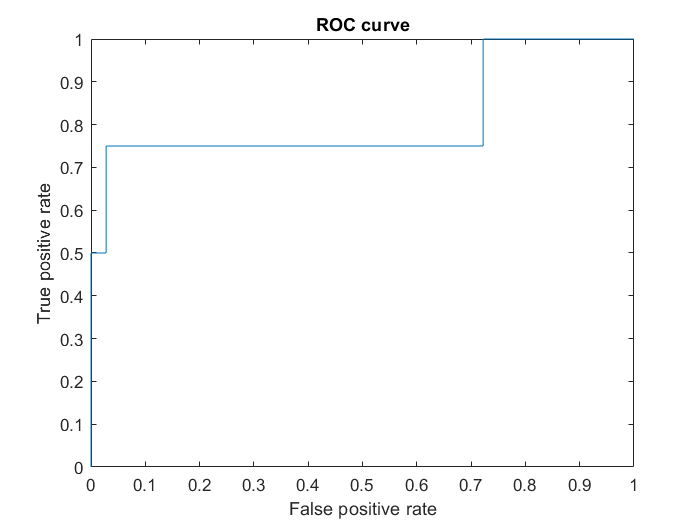

plot(X,Y)
title('ROC curve')
xlabel('False positive rate') 
ylabel('True positive rate')

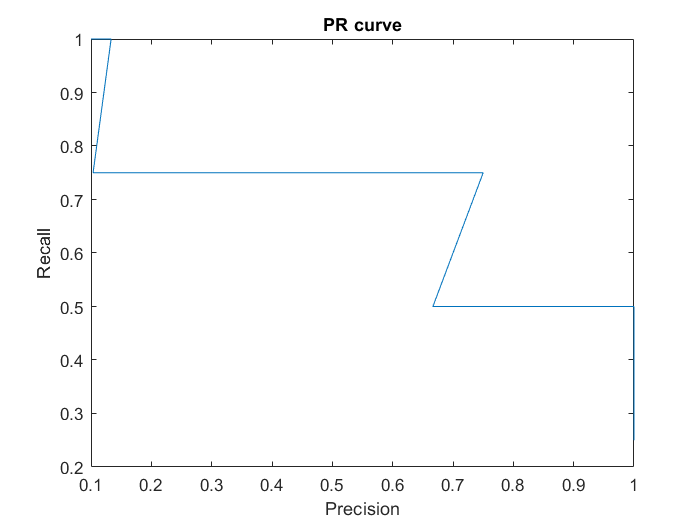

[X,Y] = perfcurve(dataTest.Class,scores(:,1),'-1','XCrit','prec','YCrit','reca');
plot(X,Y)
xlabel('Precision')
ylabel('Recall')
title('PR curve')

Задание 3

clear
glass = readtable('glass.csv')

glass = 214×11 table
    Id      RI       Na       Mg      Al      Si       K       Ca     Ba     Fe     Type
    __    ______    _____    ____    ____    _____    ____    ____    __    ____    ____

     1     1.521    13.64    4.49     1.1    71.78    0.06    8.75    0        0     1  
     2    1.5176    13.89     3.6    1.36    72.73    0.48    7.83    0        0     1  
     3    1.5162    13.53    3.55    1.54    72.99    0.39    7.78    0        0     1  
     4    1.5177    13.21    3.69    1.29    72.61    0.57    8.22    0        0     1  
     5    1.5174    13.27    3.62    1.24    73.08    0.55    8.07    

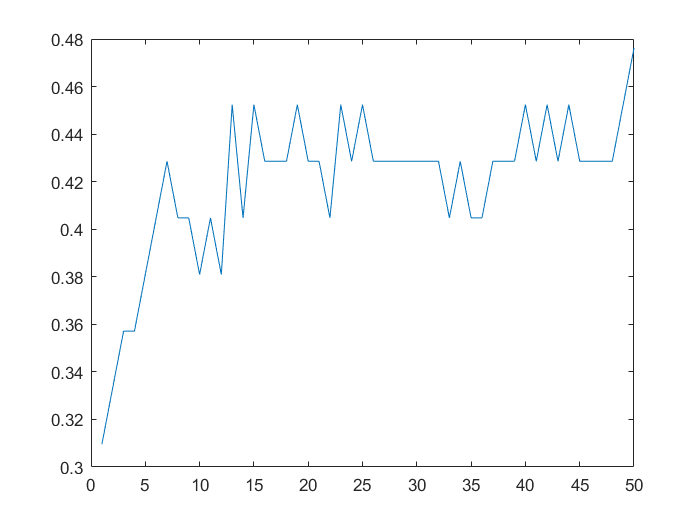

glass = glass(:,2:end);
cvpt = cvpartition(glass.Type,"HoldOut",0.2);
dataTrain = glass(training(cvpt),:);
dataTest = glass(test(cvpt),:);
maxNum = 50;
classError = zeros(maxNum,1);
for i = 1:maxNum
    knnModel = fitcknn(dataTrain,"Type","NumNeighbors",i);
    prediction = predict(knnModel,dataTest);
    classError(i) = nnz(prediction ~= dataTest{:,end})/numel(prediction);
end
plot(1:maxNum, classError)

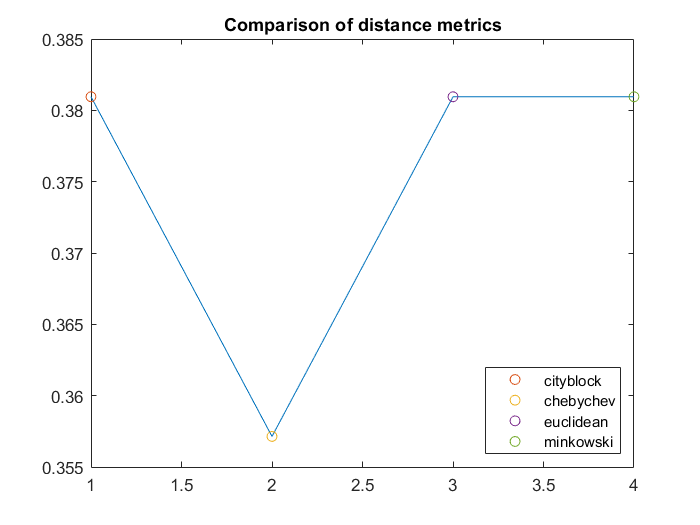


metricTypes = ["cityblock" "chebychev" "euclidean" "minkowski"];
classError = zeros(numel(metricTypes),1);
count = 1;
for metric = metricTypes
    knnModel = fitcknn(dataTrain,"Type","NumNeighbors",5,"Distance",metric);
    prediction = predict(knnModel,dataTest);
    classError(count) = nnz(prediction ~= dataTest{:,end})/numel(prediction);
    count = count + 1;
end
plot(1:numel(metricTypes), classError)
hold on
h = zeros(4,1);
for i = 1:4
    h(i) = plot(i,classError(i),'o');
end
title('Comparison of distance metrics')
legend(h,metricTypes,'Location','Southeast');
hold off


knnModel = fitcknn(dataTrain,"Type","NumNeighbors",5);

predictionSingle = predict(knnModel, [1.516 11.7 1.01 1.19 72.59 0.43 11.44 0.02 0.1])

predictionSingle = 5

Задание 4a

clear
svmdataA = readtable('svmdata_a.txt')

svmdataA = 40×4 table
    Var1      Var2          Var3        Var4  
    ____    _________    __________    _______

      1       0.14875       0.13129    {'red'}
      2     -0.048815      0.036423    {'red'}
      3     -0.062391      -0.23486    {'red'}
      4       0.35484       -0.1774    {'red'}
      5      -0.14562      0.081265    {'red'}
      6      0.087745      -0.29193    {'red'}
      7     -0.074295     -0.072756    {'red'}
      8      0.069675       0.10495    {'red'}
      9     0.0007752      -0.14214    {'red'}
     10       0.18027       0.29152    {'red'}
     11      -0.13289      0.013373    {'red'}
     12     -0.061166       0.12332    {'red'}
     13      -0.11258      0.042595    {'red'}
     14       0.12614      -0.25618    {'red'}
     15       0.10799    -0.0059265    {'red'}
     16      0.040148     -0.057326    {'r

svmdataA = svmdataA(:,2:end);
svmdataA_test = readtable('svmdata_a_test.txt')

svmdataA_test = 40×4 table
    Var1       Var2          Var3        Var4  
    ____    __________    __________    _______

      1       0.034865    -0.0029328    {'red'}
      2       -0.51089      -0.16898    {'red'}
      3        0.11719      -0.18916    {'red'}
      4        0.19422      0.087315    {'red'}
      5        0.22387      0.082128    {'red'}
      6       0.042781       0.18234    {'red'}
      7       -0.10438      -0.28666    {'red'}
      8       -0.07923       0.08591    {'red'}
      9       -0.21785      0.059281    {'red'}
     10     -0.0080422     -0.013445    {'red'}
     11       -0.19334      -0.12331    {'red'}
     12       0.082004      0.033079    {'red'}
     13       0.036226      0.054967    {'red'}
     14       0.051985      -0.10682    {'red'}
     15       -0.28248      0.071522    {'red'}
     16        0.251

svmdataA_test = svmdataA_test(:,2:end);
svmModel = fitcsvm(svmdataA,"Var4","KernelFunction","linear")

svmModel =   ClassificationSVM
           PredictorNames: {'Var2'  'Var3'}
             ResponseName: 'Var4'
    CategoricalPredictors: []
               ClassNames: {'green'  'red'}
           ScoreTransform: 'none'
          NumObservations: 40
                    Alpha: [6×1 double]
                     Bias: 1.3161
         KernelParameters: [1×1 struct]
           BoxConstraints: [40×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [40×1 logical]
                   Solver: 'SMO'


  Properties, Methods



supportVectorCount = nnz(svmModel.IsSupportVector)

supportVectorCount = 6

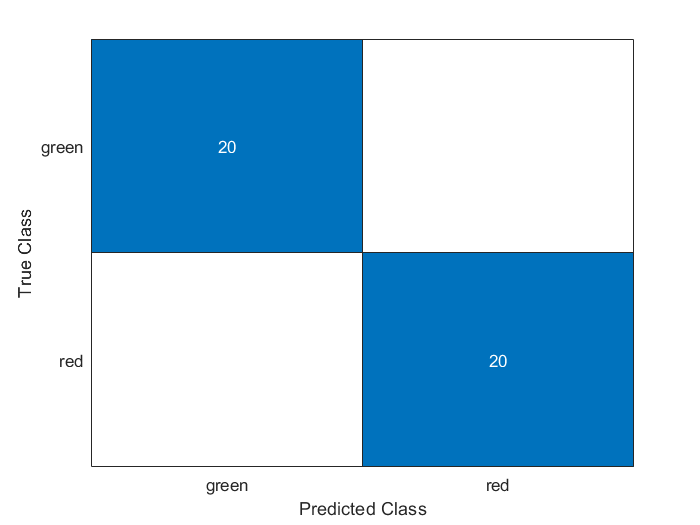


testPrediction = predict(svmModel,svmdataA_test);
resubPrediction = resubPredict(svmModel);
confusionchart(svmdataA_test{:,end},testPrediction)

confusionchart(svmdataA{:,end},resubPrediction)

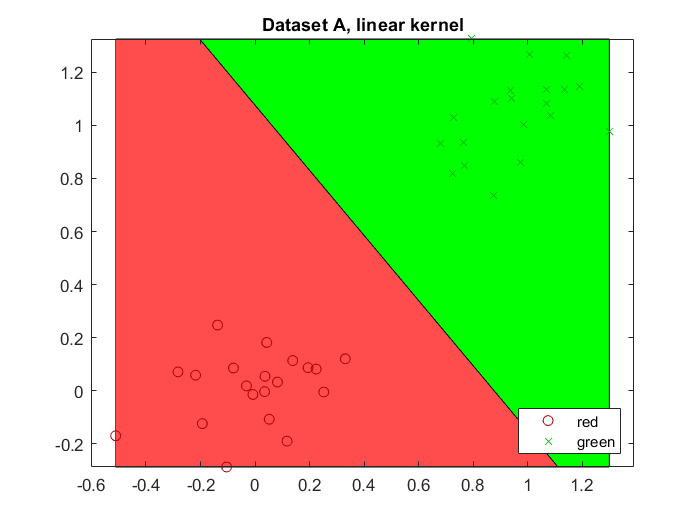


[x1Grid,x2Grid] = meshgrid(linspace(min(svmdataA_test{:,1}),max(svmdataA_test{:,1}),100),...
    linspace(min(svmdataA_test{:,2}),max(svmdataA_test{:,2}),100));
[~,scores] = predict(svmModel,[x1Grid(:),x2Grid(:)]);

plotSVM(svmdataA_test,scores,x1Grid,x2Grid,'Dataset A, linear kernel');

Задание 4b

clear
svmdataB = readtable('svmdata_b.txt')

svmdataB = 50×4 table
    Var1       Var2          Var3         Var4  
    ____    __________    ___________    _______

      1       0.076976       -0.39321    {'red'}
      2       -0.55339        0.21236    {'red'}
      3        0.53548      -0.053169    {'red'}
      4     -0.0010371    -9.7697e-06    {'red'}
      5       -0.12108        0.46464    {'red'}
      6       -0.20195        -0.1437    {'red'}
      7        0.47411        0.31394    {'red'}
      8       -0.46431       0.019921    {'red'}
      9       -0.70145       -0.37302    {'red'}
     10         0.3547         0.1244    {'red'}
     11        0.60874         0.6256    {'red'}
     12        0.29249        -0.4198    {'red'}
     13       0.023573       -0.29515    {'red'}
     14        0.24902       -0.23693    {'red'}
     15        0.39732       -0.62372    {'red'}
     16 

svmdataB = svmdataB(:,2:end);
svmdataB_test = readtable('svmdata_b_test.txt')

svmdataB_test = 50×4 table
    Var1      Var2         Var3        Var4  
    ____    _________    _________    _______

      1       0.46893       0.3662    {'red'}
      2      -0.38249     -0.53404    {'red'}
      3       0.19608      0.11956    {'red'}
      4     -0.065208     -0.74987    {'red'}
      5      -0.18368      -0.7331    {'red'}
      6      0.070058    -0.075363    {'red'}
      7      -0.34398      0.39754    {'red'}
      8      -0.12274     0.050874    {'red'}
      9      0.018711      0.40491    {'red'}
     10       0.15003     -0.14355    {'red'}
     11       0.04282     -0.74165    {'red'}
     12        0.1934      -0.5122    {'red'}
     13      -0.82833      0.23713    {'red'}
     14        0.1003       0.3471    {'red'}
     15      -0.41603     -0.76216    {'red'}
     16      -0.62954     -0.22059    {'red'}


svmdataB_test = svmdataB_test(:,2:end);

constraintValues = [1, 10, 100, 100, 1000, 10000];
testAccuracy = zeros(1,length(constraintValues));
resubAccuracy = zeros(1,length(constraintValues));
accIndex = 1;
for C = constraintValues
    svmModel = fitcsvm(svmdataB,"Var4","KernelFunction","linear","BoxConstraint",C);
    testPrediction = predict(svmModel,svmdataB_test);
    resubPrediction = resubPredict(svmModel);
    testAccuracy(accIndex) = nnz(string(testPrediction) == string(svmdataB_test{:,end}))/numel(testPrediction);
    resubAccuracy(accIndex) = nnz(string(resubPrediction) == string(svmdataB{:,end}))/numel(resubPrediction);
    accIndex = accIndex + 1;
end
testAccuracy

testAccuracy =     1.0000    1.0000    1.0000    1.0000    0.9400    0.9400


resubAccuracy

resubAccuracy =     0.9800    0.9800    0.9800    0.9800    1.0000    1.0000


Задание 4c

clear
svmdataC = readtable('svmdata_c.txt')

svmdataC = 50×4 table
    Var1      Var2        Var3         Var4   
    ____    ________    _________    _________

      1     -0.33547      0.10224    {'red'  }
      2      0.67185      0.78754    {'green'}
      3       1.9169     -0.90965    {'green'}
      4     -0.58236      0.63242    {'red'  }
      5     -0.32923      0.92799    {'red'  }
      6      -0.9847    -0.051039    {'red'  }
      7     -0.52088      -0.5132    {'red'  }
      8     -0.37172     -0.15562    {'red'  }
      9     -0.28921      0.24602    {'red'  }
     10      0.16564     -0.64256    {'red'  }
     11        -3.04       1.4789    {'green'}
     12       1.3102       1.2204    {'green'}
     13      -1.2334     -0.47216    {'green'}
     14       0.7153      0.92417    {'green'}
     15       1.9754      -1.4529    {'green'}
     16      -1.0225     -0.78245    {'gre

svmdataC = svmdataC(:,2:end);
svmdataC_test = readtable('svmdata_c_test.txt')

svmdataC_test = 50×4 table
    Var1      Var2         Var3        Var4   
    ____    _________    ________    _________

      1         2.057     0.76304    {'green'}
      2       0.25591     -0.3791    {'red'  }
      3      -0.27855       1.601    {'green'}
      4        1.0078    -0.49435    {'green'}
      5     -0.031791     -1.0429    {'green'}
      6        1.5173     0.71161    {'green'}
      7        0.7946    -0.56734    {'red'  }
      8      -0.86125     0.17928    {'red'  }
      9      -0.77067     0.50969    {'red'  }
     10       0.24625     0.64591    {'red'  }
     11      -0.65513      1.0405    {'green'}
     12     -0.097654    0.049536    {'red'  }
     13       -1.1936     0.40033    {'green'}
     14         1.945     0.23357    {'green'}
     15      -0.35386    -0.18355    {'red'  }
     16        1.0449    0.064307    

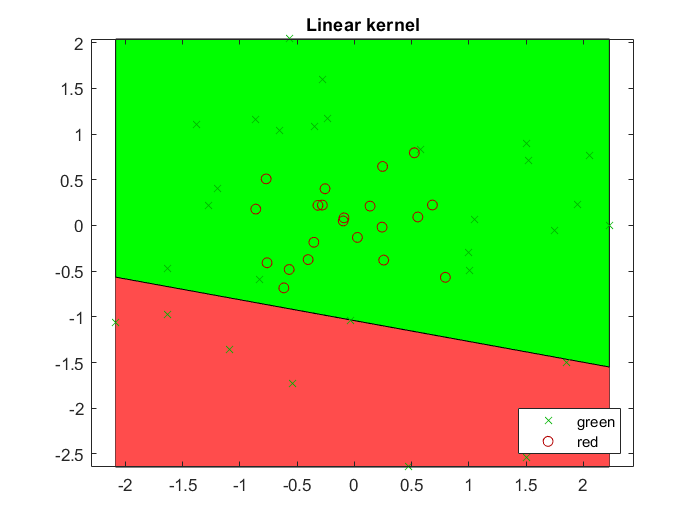

svmdataC_test = svmdataC_test(:,2:end);

[x1Grid,x2Grid] = meshgrid(linspace(min(svmdataC_test{:,1}),max(svmdataC_test{:,1}),100),...
    linspace(min(svmdataC_test{:,2}),max(svmdataC_test{:,2}),100));
svmModel = fitcsvm(svmdataC,"Var4","KernelFunction","linear");
[~,scores] = predict(svmModel,[x1Grid(:),x2Grid(:)]);
plotSVM(svmdataC_test,scores,x1Grid,x2Grid,'Linear kernel');

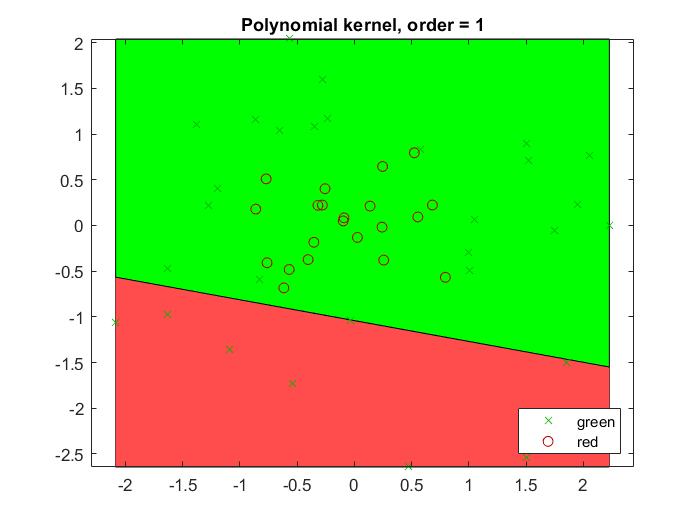

svmModel = fitcsvm(svmdataC,"Var4","KernelFunction","polynomial","PolynomialOrder",1);
[~,scores] = predict(svmModel,[x1Grid(:),x2Grid(:)]);
plotSVM(svmdataC_test,scores,x1Grid,x2Grid,'Polynomial kernel, order = 1');

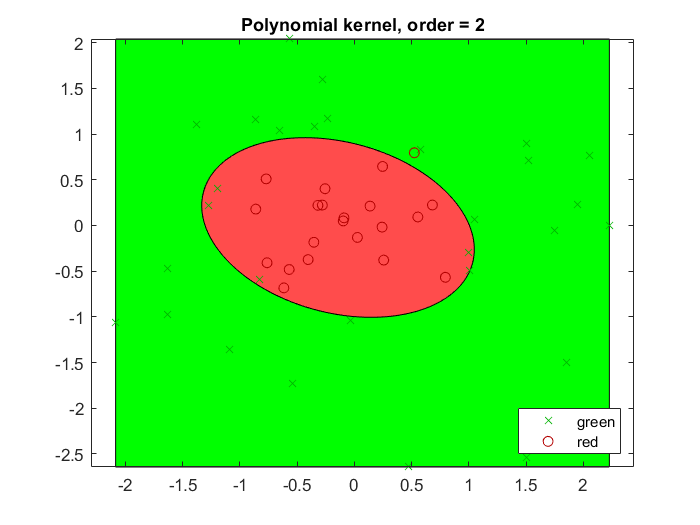

svmModel = fitcsvm(svmdataC,"Var4","KernelFunction","polynomial","PolynomialOrder",2);
[~,scores] = predict(svmModel,[x1Grid(:),x2Grid(:)]);
plotSVM(svmdataC_test,scores,x1Grid,x2Grid,'Polynomial kernel, order = 2');

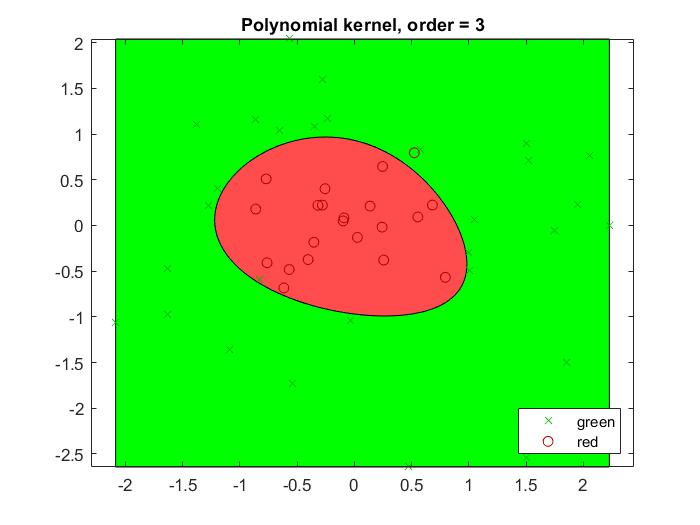

svmModel = fitcsvm(svmdataC,"Var4","KernelFunction","polynomial","PolynomialOrder",3);
[~,scores] = predict(svmModel,[x1Grid(:),x2Grid(:)]);
plotSVM(svmdataC_test,scores,x1Grid,x2Grid,'Polynomial kernel, order = 3');

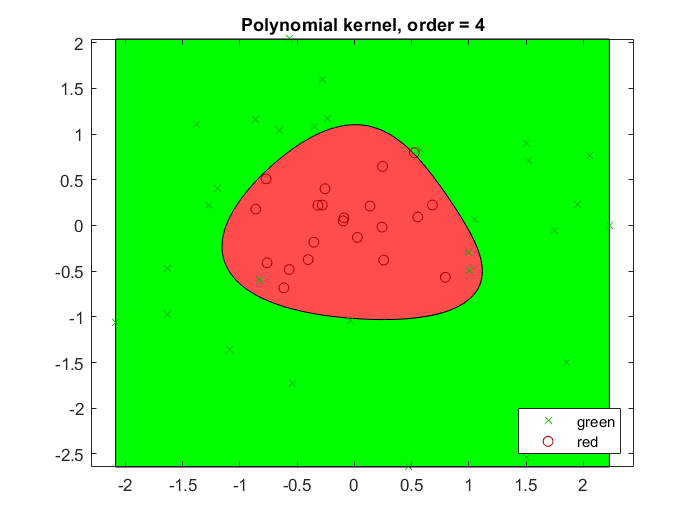

svmModel = fitcsvm(svmdataC,"Var4","KernelFunction","polynomial","PolynomialOrder",4);
[~,scores] = predict(svmModel,[x1Grid(:),x2Grid(:)]);
plotSVM(svmdataC_test,scores,x1Grid,x2Grid,'Polynomial kernel, order = 4');

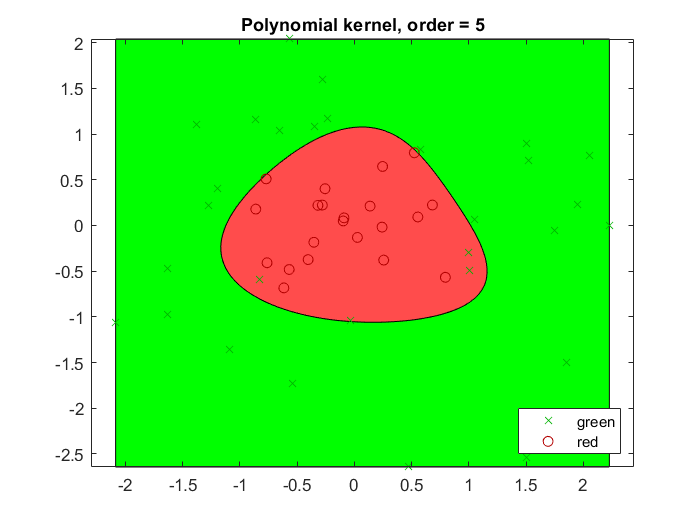

svmModel = fitcsvm(svmdataC,"Var4","KernelFunction","polynomial","PolynomialOrder",5);
[~,scores] = predict(svmModel,[x1Grid(:),x2Grid(:)]);
plotSVM(svmdataC_test,scores,x1Grid,x2Grid,'Polynomial kernel, order = 5');

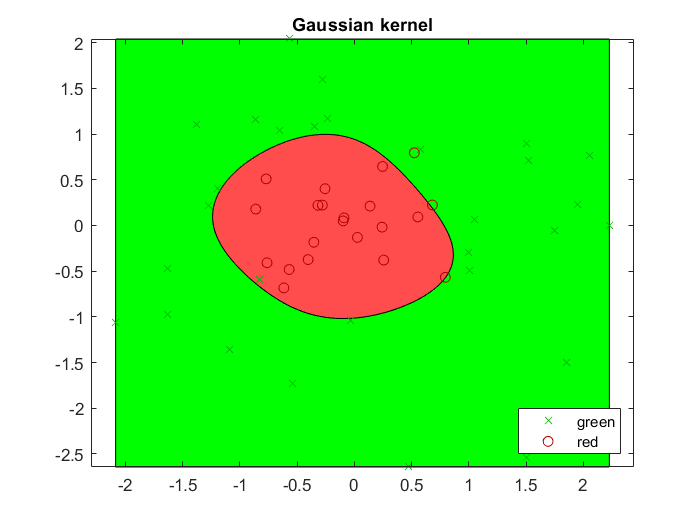

svmModel = fitcsvm(svmdataC,"Var4","KernelFunction","gaussian");
[~,scores] = predict(svmModel,[x1Grid(:),x2Grid(:)]);
plotSVM(svmdataC_test,scores,x1Grid,x2Grid,'Gaussian kernel');

Задание 4d

clear
svmdataD = readtable('svmdata_d.txt')

svmdataD = 200×4 table
    Var1     Var2       Var3        Var4   
    ____    ______    ________    _________

      1     11.503    -0.87202    {'green'}
      2     6.9522    -0.36824    {'red'  }
      3     9.1576       1.058    {'green'}
      4     3.9216       1.703    {'green'}
      5     4.0196     0.70616    {'green'}
      6     11.463      1.3149    {'green'}
      7     11.811     0.44995    {'green'}
      8     7.5519      1.3135    {'green'}
      9     2.5206     0.48671    {'red'  }
     10     11.679    -0.16271    {'green'}
     11       5.48      1.6692    {'green'}
     12     1.2383      1.2363    {'green'}
     13     11.601     -0.7488    {'green'}
     14     8.9981    0.087751    {'red'  }
     15     7.7545    -0.99634    {'red'  }
     16     11.927     -1.1148    {'red'  }


svmdataD = svmdataD(:,2:end);
svmdataD_test = readtable('svmdata_d_test.txt')

svmdataD_test = 200×4 table
    Var1     Var2       Var3        Var4   
    ____    ______    ________    _________

      1      5.722    -0.40199    {'green'}
      2      4.673    -0.96801    {'green'}
      3     8.7913      -1.999    {'red'  }
      4     2.4912      1.1439    {'green'}
      5     3.8051      1.3292    {'green'}
      6     6.4096      1.8845    {'green'}
      7     7.2809     -0.9447    {'red'  }
      8     11.322      1.2811    {'green'}
      9     5.3746     0.96796    {'green'}
     10     8.0784     -1.8184    {'red'  }
     11     9.9161     -1.2793    {'red'  }
     12      7.332      1.6038    {'green'}
     13     6.4731      1.7207    {'green'}
     14     3.9406    -0.57232    {'green'}
     15     4.0771      1.1495    {'green'}
     16     3.4477     0.53931    {'green'}


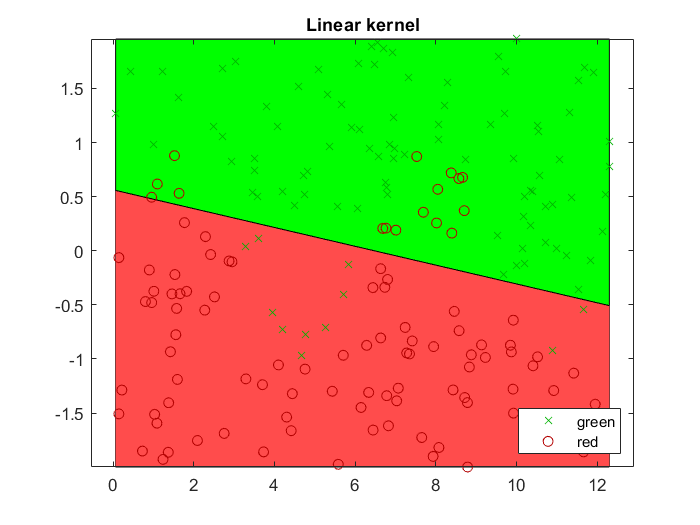

svmdataD_test = svmdataD_test(:,2:end);

[x1Grid,x2Grid] = meshgrid(linspace(min(svmdataD_test{:,1}),max(svmdataD_test{:,1}),100),...
    linspace(min(svmdataD_test{:,2}),max(svmdataD_test{:,2}),100));
svmModel = fitcsvm(svmdataD,"Var4","KernelFunction","linear");
[~,scores] = predict(svmModel,[x1Grid(:),x2Grid(:)]);
plotSVM(svmdataD_test,scores,x1Grid,x2Grid,'Linear kernel');

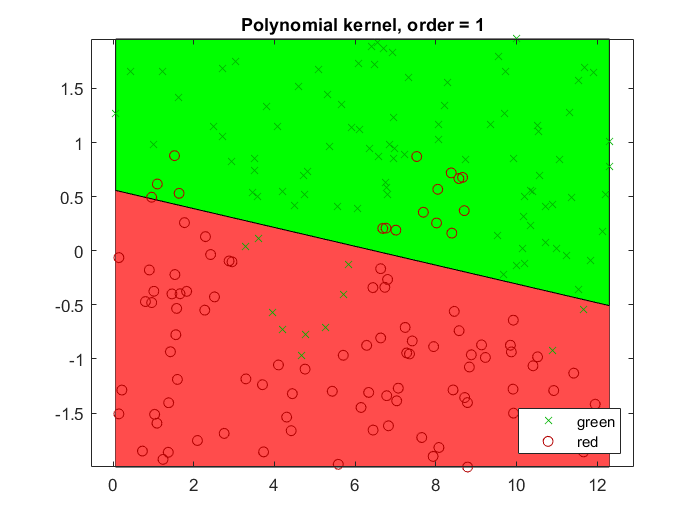

svmModel = fitcsvm(svmdataD,"Var4","KernelFunction","polynomial","PolynomialOrder",1);
[~,scores] = predict(svmModel,[x1Grid(:),x2Grid(:)]);
plotSVM(svmdataD_test,scores,x1Grid,x2Grid,'Polynomial kernel, order = 1');

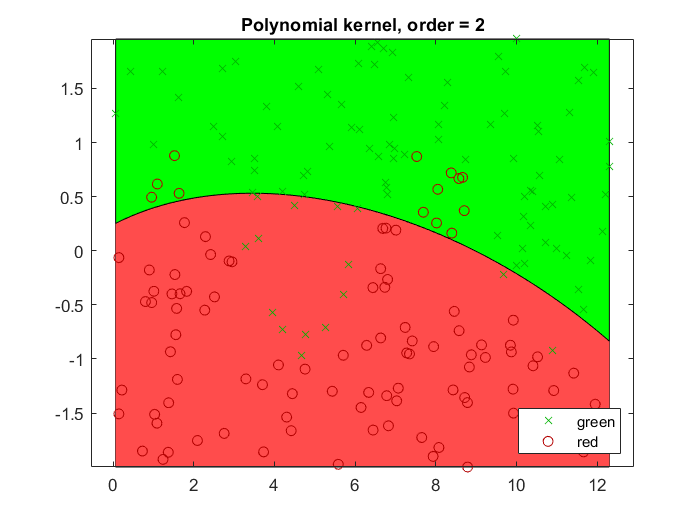

svmModel = fitcsvm(svmdataD,"Var4","KernelFunction","polynomial","PolynomialOrder",2);
[~,scores] = predict(svmModel,[x1Grid(:),x2Grid(:)]);
plotSVM(svmdataD_test,scores,x1Grid,x2Grid,'Polynomial kernel, order = 2');

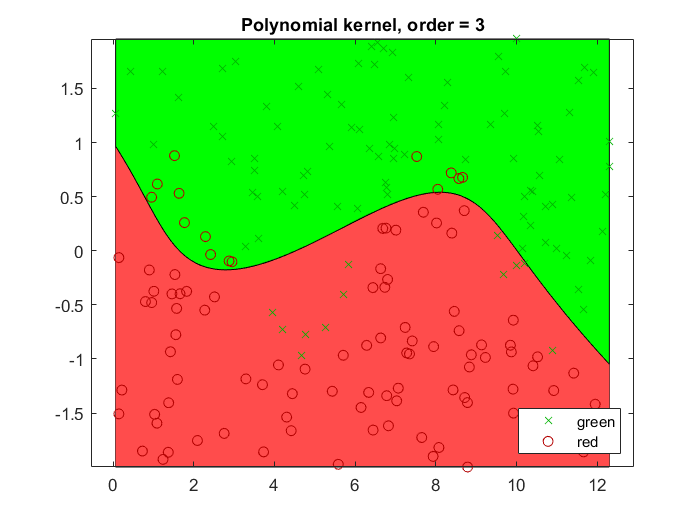

svmModel = fitcsvm(svmdataD,"Var4","KernelFunction","polynomial","PolynomialOrder",3);
[~,scores] = predict(svmModel,[x1Grid(:),x2Grid(:)]);
plotSVM(svmdataD_test,scores,x1Grid,x2Grid,'Polynomial kernel, order = 3');

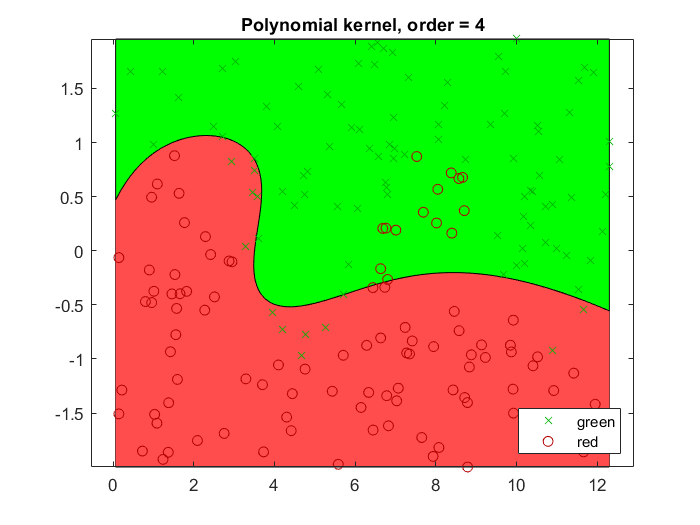

svmModel = fitcsvm(svmdataD,"Var4","KernelFunction","polynomial","PolynomialOrder",4);
[~,scores] = predict(svmModel,[x1Grid(:),x2Grid(:)]);
plotSVM(svmdataD_test,scores,x1Grid,x2Grid,'Polynomial kernel, order = 4');

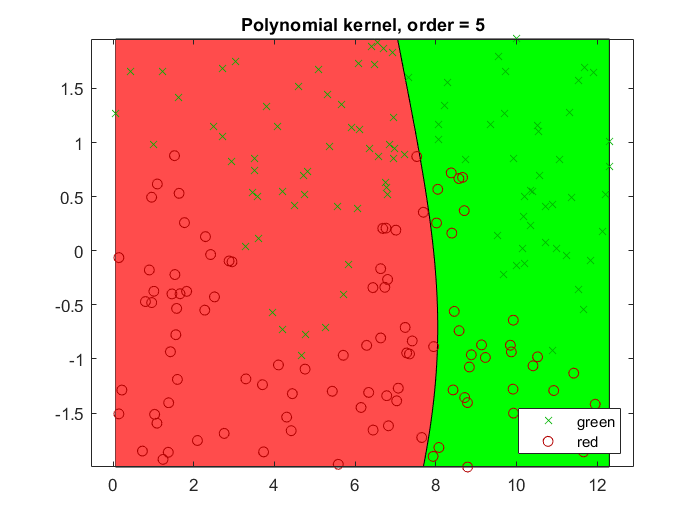

svmModel = fitcsvm(svmdataD,"Var4","KernelFunction","polynomial","PolynomialOrder",5);
[~,scores] = predict(svmModel,[x1Grid(:),x2Grid(:)]);
plotSVM(svmdataD_test,scores,x1Grid,x2Grid,'Polynomial kernel, order = 5');

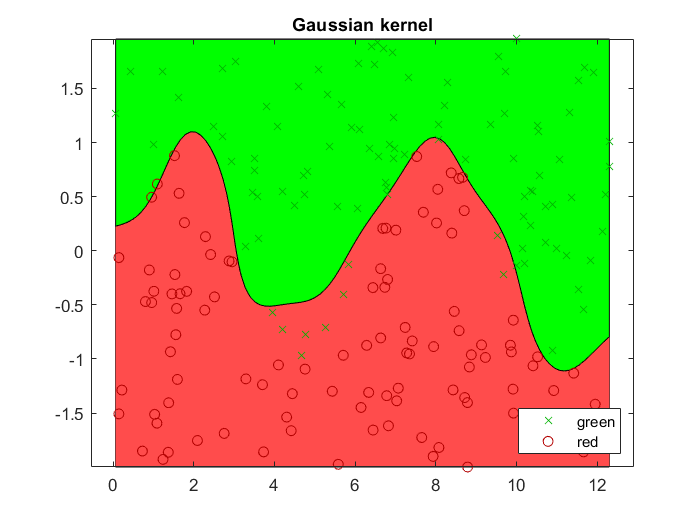

svmModel = fitcsvm(svmdataD,"Var4","KernelFunction","gaussian");
[~,scores] = predict(svmModel,[x1Grid(:),x2Grid(:)]);
plotSVM(svmdataD_test,scores,x1Grid,x2Grid,'Gaussian kernel');

Задание 4e

clear
svmdataE = readtable('svmdata_e.txt')

svmdataE = 120×4 table
    Var1      Var2        Var3       Var4  
    ____    _________    _______    _______

      1      -0.48178    0.54761    {'red'}
      2      -0.28447    0.83582    {'red'}
      3       -0.3241    0.97698    {'red'}
      4     -0.078877    0.36304    {'red'}
      5     -0.021214    0.80451    {'red'}
      6      -0.25406    0.89303    {'red'}
      7      -0.67984    0.43002    {'red'}
      8       -0.6021    0.32049    {'red'}
      9      -0.10689    0.71433    {'red'}
     10      -0.57447     0.8692    {'red'}
     11      -0.71553    0.72511    {'red'}
     12         -0.46    0.09723    {'red'}
     13      -0.18621    0.61531    {'red'}
     14      -0.95953    0.27223    {'red'}
     15     -0.023136    0.45589    {'red'}
     16      -0.38654    0.34725    {'red'}


svmdataE = svmdataE(:,2:end);
svmdataE_test = readtable('svmdata_e_test.txt')

svmdataE_test = 120×4 table
    Var1      Var2         Var3       Var4  
    ____    _________    ________    _______

      1      -0.48178     0.68549    {'red'}
      2      -0.28447    0.014696    {'red'}
      3       -0.3241     0.99189    {'red'}
      4     -0.078877     0.66347    {'red'}
      5     -0.021214    0.014931    {'red'}
      6      -0.25406     0.29313    {'red'}
      7      -0.67984     0.82278    {'red'}
      8       -0.6021     0.57264    {'red'}
      9      -0.10689     0.75306    {'red'}
     10      -0.57447     0.27904    {'red'}
     11      -0.71553     0.28202    {'red'}
     12         -0.46     0.42746    {'red'}
     13      -0.18621     0.87418    {'red'}
     14      -0.95953     0.91336    {'red'}
     15     -0.023136     0.46623    {'red'}
     16      -0.38654    0.059079    {'red'}


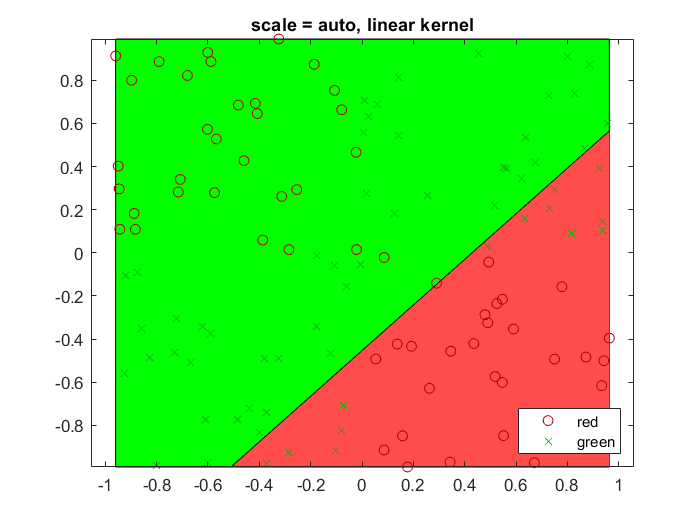

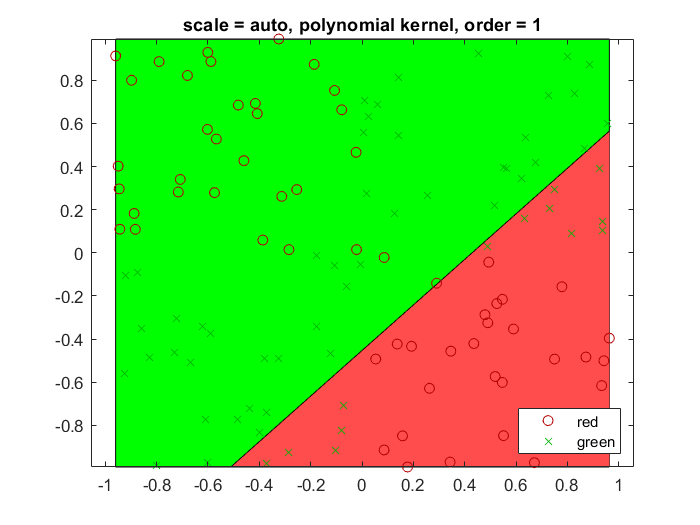

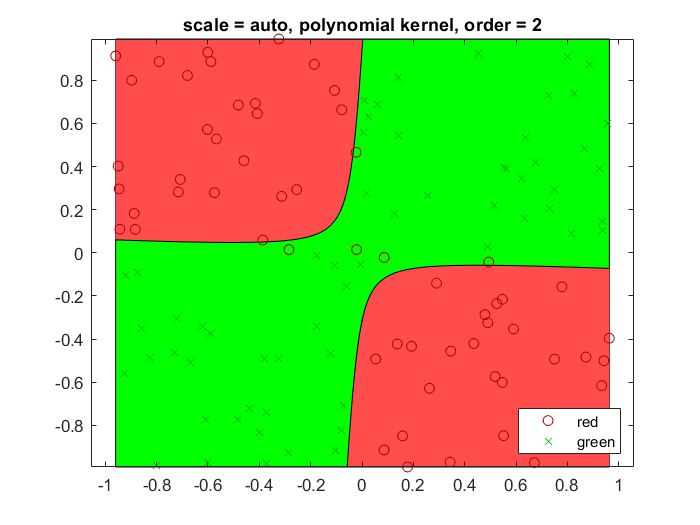

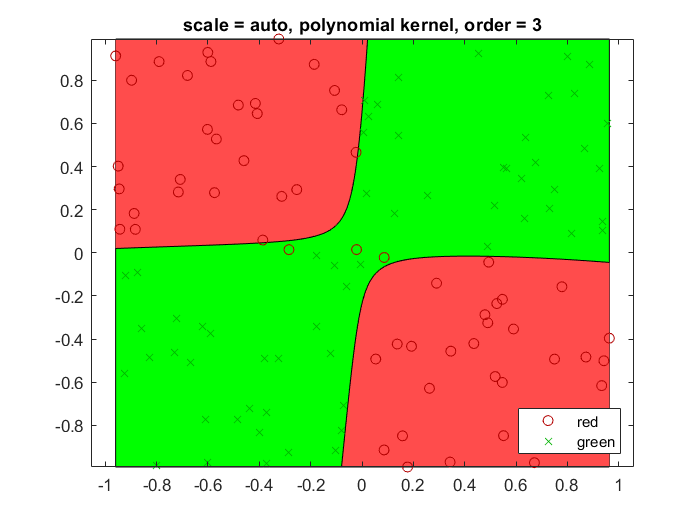

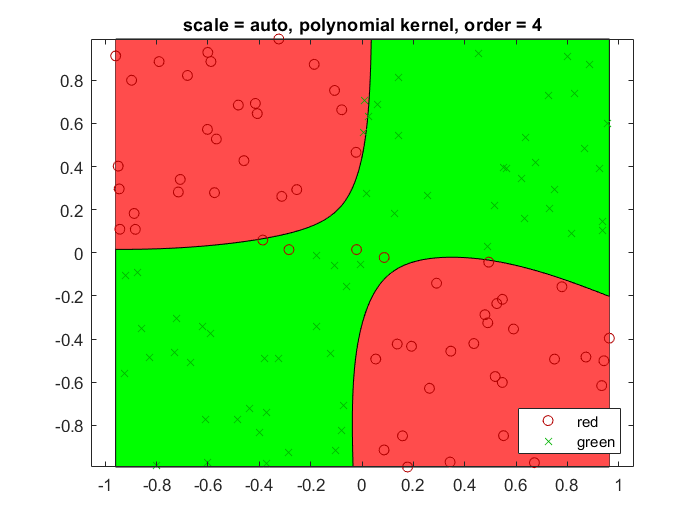

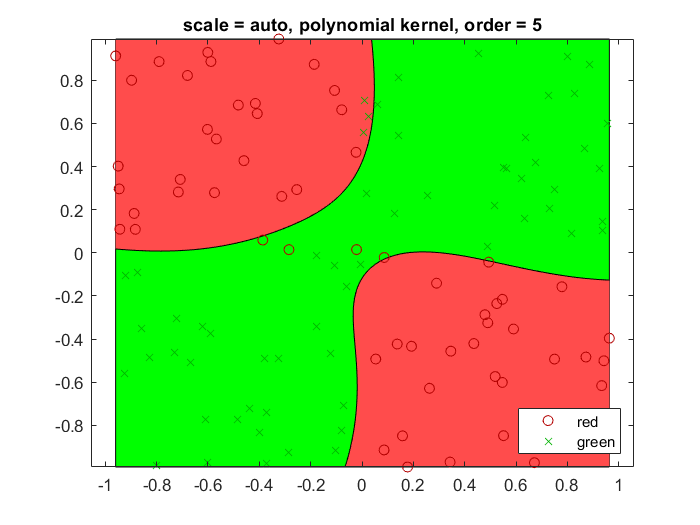

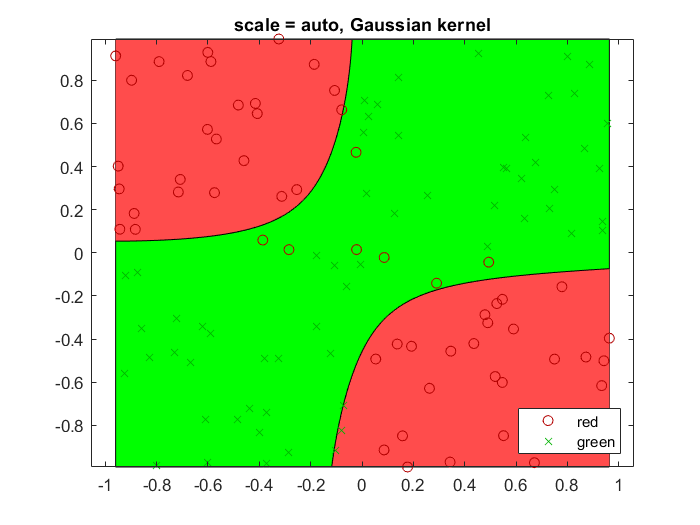

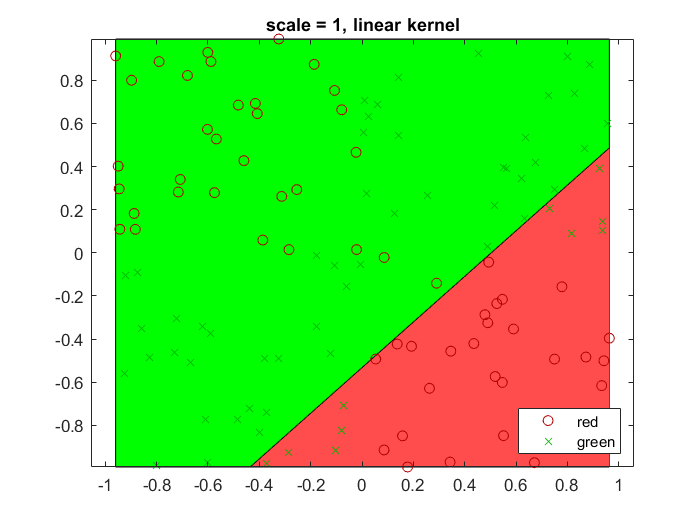

svmdataE_test = svmdataE_test(:,2:end);

scaleOptions = {'auto' 1 10 100};
[x1Grid,x2Grid] = meshgrid(linspace(min(svmdataE_test{:,1}),max(svmdataE_test{:,1}),100),...
    linspace(min(svmdataE_test{:,2}),max(svmdataE_test{:,2}),100));
for scale = scaleOptions
    svmModel = fitcsvm(svmdataE,"Var4","KernelFunction","linear","KernelScale",scale{1});
    [~,scores] = predict(svmModel,[x1Grid(:),x2Grid(:)]);
    plotSVM(svmdataE_test,scores,x1Grid,x2Grid,'scale = ' + string(scale{1}) +', linear kernel');
    svmModel = fitcsvm(svmdataE,"Var4","KernelFunction","polynomial","PolynomialOrder",1,"KernelScale",scale{1});
    [~,scores] = predict(svmModel,[x1Grid(:),x2Grid(:)]);
    plotSVM(svmdataE_test,scores,x1Grid,x2Grid,'scale = ' + string(scale{1}) + ', polynomial kernel, order = 1');
    svmModel = fitcsvm(svmdataE,"Var4","KernelFunction","polynomial","PolynomialOrder",2,"KernelScale",scale{1});
    [~,scores] = predict(svmModel,[x1Grid(:),x2Grid(:)]);
    plotSVM(svmdataE_test,scores,x1Grid,x2Grid,'scale = ' + string(scale{1}) + ', polynomial kernel, order = 2');
    svmModel = fitcsvm(svmdataE,"Var4","KernelFunction","polynomial","PolynomialOrder",3,"KernelScale",scale{1});
    [~,scores] = predict(svmModel,[x1Grid(:),x2Grid(:)]);
    plotSVM(svmdataE_test,scores,x1Grid,x2Grid,'scale = ' + string(scale{1}) + ', polynomial kernel, order = 3');
    svmModel = fitcsvm(svmdataE,"Var4","KernelFunction","polynomial","PolynomialOrder",4,"KernelScale",scale{1});
    [~,scores] = predict(svmModel,[x1Grid(:),x2Grid(:)]);
    plotSVM(svmdataE_test,scores,x1Grid,x2Grid,'scale = ' + string(scale{1}) + ', polynomial kernel, order = 4');
    svmModel = fitcsvm(svmdataE,"Var4","KernelFunction","polynomial","PolynomialOrder",5,"KernelScale",scale{1});
    [~,scores] = predict(svmModel,[x1Grid(:),x2Grid(:)]);
    plotSVM(svmdataE_test,scores,x1Grid,x2Grid,'scale = ' + string(scale{1}) + ', polynomial kernel, order = 5');
    svmModel = fitcsvm(svmdataE,"Var4","KernelFunction","gaussian");
    [~,scores] = predict(svmModel,[x1Grid(:),x2Grid(:)]);
    plotSVM(svmdataE_test,scores,x1Grid,x2Grid,'scale = ' + string(scale{1}) + ', Gaussian kernel');
end

Задание 5a

clear
glass = readtable('glass.csv');
glass = glass(:,2:end)

glass = 214×10 table
      RI       Na       Mg      Al      Si       K       Ca     Ba     Fe     Type
    ______    _____    ____    ____    _____    ____    ____    __    ____    ____

     1.521    13.64    4.49     1.1    71.78    0.06    8.75    0        0     1  
    1.5176    13.89     3.6    1.36    72.73    0.48    7.83    0        0     1  
    1.5162    13.53    3.55    1.54    72.99    0.39    7.78    0        0     1  
    1.5177    13.21    3.69    1.29    72.61    0.57    8.22    0        0     1  
    1.5174    13.27    3.62    1.24    73.08    0.55    8.07    0        0     1  
     1.516    12.79    3.61    1.62    72.97    0.64    8

cvpt = cvpartition(glass.Type,"HoldOut",0.2);
dataTrain = glass(training(cvpt),:);
dataTest = glass(test(cvpt),:);

treeModel = fitctree(dataTrain,"Type")

treeModel =   ClassificationTree
           PredictorNames: {'RI'  'Na'  'Mg'  'Al'  'Si'  'K'  'Ca'  'Ba'  'Fe'}
             ResponseName: 'Type'
    CategoricalPredictors: []
               ClassNames: [1 2 3 5 6 7]
           ScoreTransform: 'none'
          NumObservations: 172


  Properties, Methods


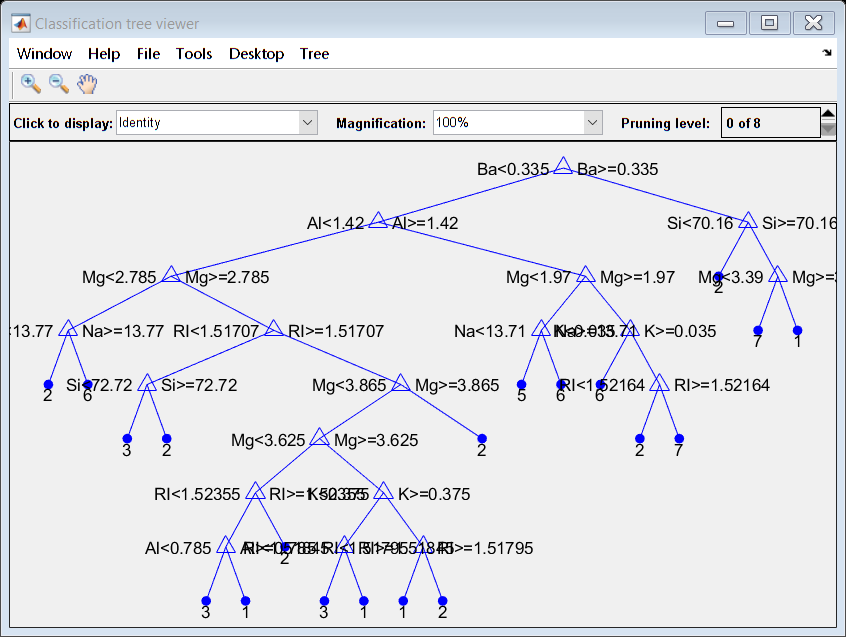

view(treeModel,'Mode','graph')

prediction = predict(treeModel,dataTest);
accuracy = nnz(prediction == dataTest{:,end})/numel(prediction)

accuracy = 0.7143

maxSplitsOptions = 1:10;
minLeafOptions = 1:5;
pruneOptions = ["on" "off"];
pruneCriterionOptions = ["error" "impurity"];
mergeOptions = ["on" "off"];
optionTable = table('Size',[numel(maxSplitsOptions)*numel(minLeafOptions)*numel(pruneOptions)*numel(pruneCriterionOptions)*numel(mergeOptions) 6],'VariableTypes',{'int8','int8','string','string','string','double'},'VariableNames',{'Max Splits','Min Leaf Size','Prune','Prune Criterion','Merge Leaves','Accuracy'});
tIndex = 1;
for maxSplits = maxSplitsOptions   
    for minLeaf = minLeafOptions
        for isPrune = pruneOptions
            for pruneCrit = pruneCriterionOptions
                for mergeLeaves = mergeOptions
                    optionTable{tIndex,1} = maxSplits;
                    optionTable{tIndex,2} = minLeaf;
                    optionTable{tIndex,3} = isPrune;
                    optionTable{tIndex,4} = pruneCrit;
                    optionTable{tIndex,5} = mergeLeaves;
                    treeModel = fitctree(glass,"Type","MaxNumSplits",maxSplits,"MinLeafSize",minLeaf,"Prune",isPrune,"PruneCriterion",pruneCrit,"MergeLeaves",mergeLeaves);
                    prediction = predict(treeModel,dataTest);
                    optionTable{tIndex,6} = nnz(prediction == dataTest{:,end})/numel(prediction);
                    tIndex = tIndex + 1;
                end
            end
        end
    end
end
optionTable

optionTable = 400×6 table
    Max Splits    Min Leaf Size    Prune    Prune Criterion    Merge Leaves    Accuracy
    __________    _____________    _____    _______________    ____________    ________

        1               1          "on"       "error"             "on"         0.47619 
        1               1          "on"       "error"             "off"        0.47619 
        1               1          "on"       "impurity"          "on"         0.47619 
        1               1          "on"       "impurity"          "off"        0.47619 
        1               1          "off"      "error"             "on"         0.47619 
        1               1          "off"      "error"             "off"        0.47619 
        1               1          "off"      "impurity"         

optionTable = sortrows(optionTable,'Accuracy','descend')

optionTable = 400×6 table
    Max Splits    Min Leaf Size    Prune    Prune Criterion    Merge Leaves    Accuracy
    __________    _____________    _____    _______________    ____________    ________

        10              3          "on"       "error"             "on"          0.7619 
        10              3          "on"       "error"             "off"         0.7619 
        10              3          "on"       "impurity"          "on"          0.7619 
        10              3          "on"       "impurity"          "off"         0.7619 
        10              3          "off"      "error"             "on"          0.7619 
        10              3          "off"      "error"             "off"         0.7619 
        10              3          "off"      "impurity"         

optionTable(1:10,:)

ans = 10×6 table
    Max Splits    Min Leaf Size    Prune    Prune Criterion    Merge Leaves    Accuracy
    __________    _____________    _____    _______________    ____________    ________

        10              3          "on"       "error"             "on"          0.7619 
        10              3          "on"       "error"             "off"         0.7619 
        10              3          "on"       "impurity"          "on"          0.7619 
        10              3          "on"       "impurity"          "off"         0.7619 
        10              3          "off"      "error"             "on"          0.7619 
        10              3          "off"      "error"             "off"         0.7619 
        10              3          "off"      "impurity"          "on"    

Задание 5b

clear
spam7 = readtable('spam7.csv')

spam7 = 4601×7 table
    crl_tot    dollar    bang     money    n000    make    yesno
    _______    ______    _____    _____    ____    ____    _____

      278          0     0.778       0        0       0    {'y'}
     1028       0.18     0.372    0.43     0.43    0.21    {'y'}
     2259      0.184     0.276    0.06     1.16    0.06    {'y'}
      191          0     0.137       0        0       0    {'y'}
      191          0     0.135       0        0       0    {'y'}
       54          0         0       0        0       0    {'y'}
      112      0.054     0.164       0        0       0    {'y'}
       49          0         0       0        0       0    {'y'}
     1257      0.203     0.181    0.15        0    0.15    {'y'}
      749      0.081     

cvpt = cvpartition(spam7.yesno,"HoldOut",0.2);
dataTrain = spam7(training(cvpt),:);
dataTest = spam7(test(cvpt),:);
treeModel = fitctree(dataTrain,"yesno","MaxNumSplits",10)

treeModel =   ClassificationTree
           PredictorNames: {'crl_tot'  'dollar'  'bang'  'money'  'n000'  'make'}
             ResponseName: 'yesno'
    CategoricalPredictors: []
               ClassNames: {'n'  'y'}
           ScoreTransform: 'none'
          NumObservations: 3681


  Properties, Methods


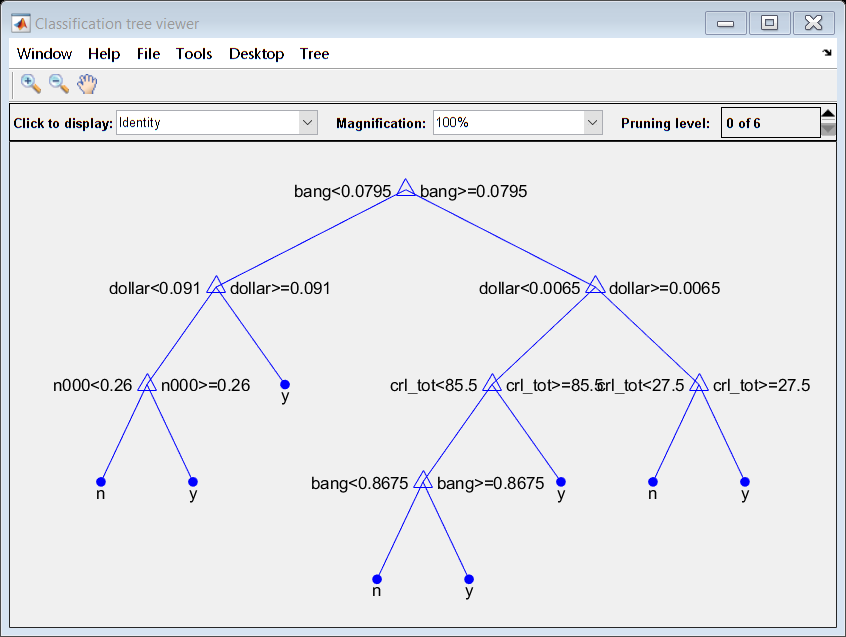

view(treeModel,'Mode','graph')

prediction = predict(treeModel,dataTest);
accuracy = nnz(string(prediction) == string(dataTest{:,end}))/numel(prediction)

accuracy = 0.8467

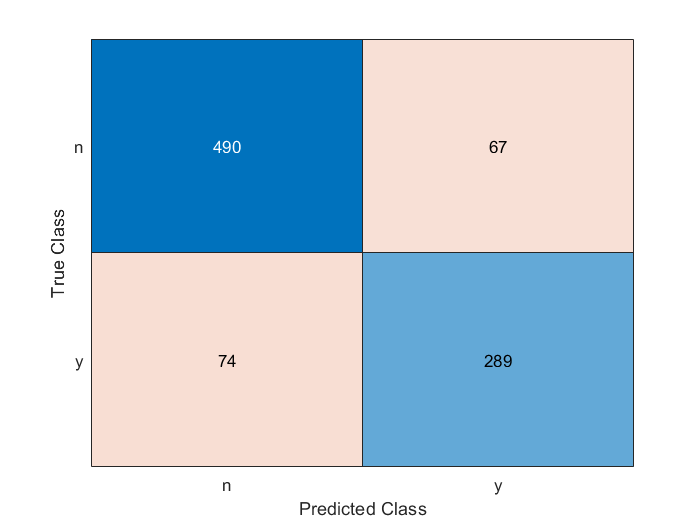

confusionchart(dataTest{:,end},prediction)

Задание 6

clear
dataTrain = readtable('bank_scoring_train.csv')

dataTrain = 96216×11 table
    SeriousDlqin2yrs    RevolvingUtilizationOfUnsecuredLines    age    NumberOfTime30_59DaysPastDueNotWorse    DebtRatio    MonthlyIncome    NumberOfOpenCreditLinesAndLoans    NumberOfTimes90DaysLate    NumberRealEstateLoansOrLines    NumberOfTime60_89DaysPastDueNotWorse    NumberOfDependents
    ________________    ____________________________________    ___    ____________________________________    _________    _____________    _______________________________    _______________________    ____________________________    ____________________________________    __________________

          

dataTest = readtable('bank_scoring_test.csv')

dataTest = 24053×11 table
    SeriousDlqin2yrs    RevolvingUtilizationOfUnsecuredLines    age    NumberOfTime30_59DaysPastDueNotWorse    DebtRatio    MonthlyIncome    NumberOfOpenCreditLinesAndLoans    NumberOfTimes90DaysLate    NumberRealEstateLoansOrLines    NumberOfTime60_89DaysPastDueNotWorse    NumberOfDependents
    ________________    ____________________________________    ___    ____________________________________    _________    _____________    _______________________________    _______________________    ____________________________    ____________________________________    __________________

           


knnModel = fitcknn(dataTrain,"SeriousDlqin2yrs","NumNeighbors",5);
prediction = predict(knnModel,dataTest);
accuracy = nnz(prediction == dataTest{:,1})/numel(prediction)

accuracy = 0.9295

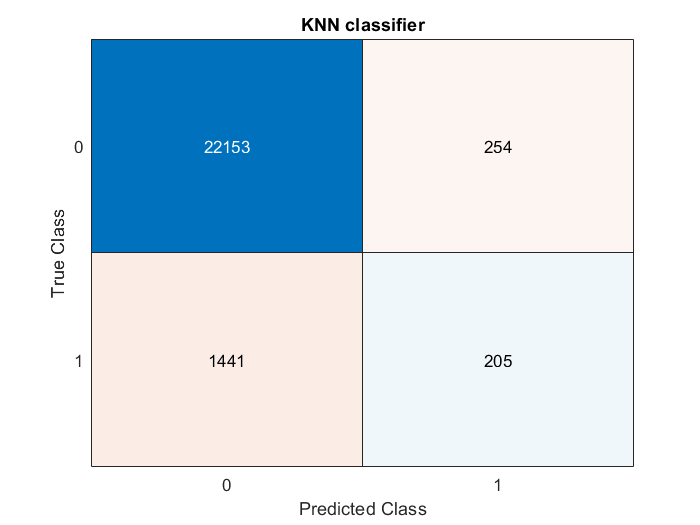

confusionchart(dataTest{:,1},prediction)
title('KNN classifier')


treeModel = fitctree(dataTrain,"SeriousDlqin2yrs","MaxNumSplits",10);
prediction = predict(treeModel,dataTest);
accuracy = nnz(prediction == dataTest{:,1})/numel(prediction)

accuracy = 0.9333

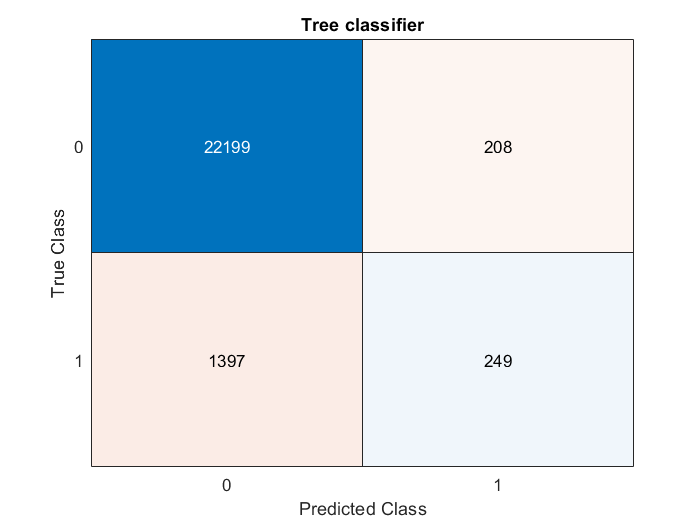

confusionchart(dataTest{:,1},prediction)
title('Tree classifier')

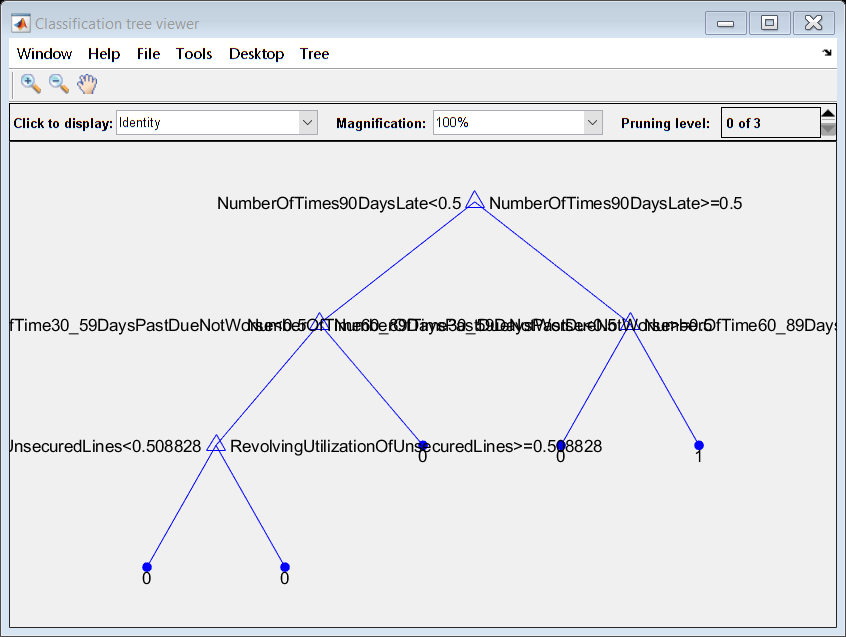

view(treeModel,'Mode','graph')

function plotDependence(data, options)    
    partRatios = 0.05:0.05:0.95;
    accuracy = zeros(1,numel(partRatios));
    accIndex = 1;
    for ratio = partRatios
        cvpt = cvpartition(data{:,end},"HoldOut",ratio);
        dataTrain = data(training(cvpt),:);
        dataTest = data(test(cvpt),:);
        nbModel = fitcnb(dataTrain,dataTrain(:,end),"DistributionNames", options);
        prediction = predict(nbModel,dataTest);
        accuracy(accIndex) = nnz(string(prediction) == string(dataTest{:,end}))/numel(prediction);
        accIndex = accIndex + 1;
    end
    figure
    plot(partRatios,accuracy,'o-')
    xlabel("Test data ratio");
    ylabel("Accuracy");
    grid on
end

function plotSVM(testData, scores, x1Grid, x2Grid, plotTitle)
    figure;
    fill([min(testData{:,1}) min(testData{:,1}) max(testData{:,1}) max(testData{:,1})],[min(testData{:,2}) max(testData{:,2}) max(testData{:,2}) min(testData{:,2})],'g')
    hold on
    map = [1 0.3 0.3];
    M = contourf(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'k');
    M = M(:, 2:end);
    colormap(map)
    h = zeros(2,1);
    firstEl = testData{1,end};
    if string(firstEl{1}) == "red"
        h(1:2) = gscatter(testData{:,1},testData{:,2},testData{:,end},[0.7 0 0; 0 0.7 0],'ox');
        legend(h,{'red','green'},'Location','Southeast');
    else
        h(1:2) = gscatter(testData{:,1},testData{:,2},testData{:,end},[0 0.7 0; 0.7 0 0],'xo');
        legend(h,{'green','red'},'Location','Southeast');
    end    
    title(plotTitle)    
    hold off
end